# **Fuzzy set operations:**

f1 = rand([1,10])

f1 =     0.7513    0.2551    0.5060    0.6991    0.8909    0.9593    0.5472    0.1386    0.1493    0.2575


f2 = rand([1,10])

f2 =     0.8407    0.2543    0.8143    0.2435    0.9293    0.3500    0.1966    0.2511    0.6160    0.4733


fuzzy_intersection = min(f1, f2)

fuzzy_intersection =     0.7513    0.2543    0.5060    0.2435    0.8909    0.3500    0.1966    0.1386    0.1493    0.2575


N = 101;
minx = -20;
maxx = 20;
x = linspace(minx,maxx,N);
A = trapmf(x,[-10 -8 1 3]);
B = gaussmf(x,[3 5]);

`trapezoidal and gaussian function`

Csum = fuzarith(x,A,B,'sum');
Csub = fuzarith(x,A,B,'sub');
Cprod = fuzarith(x,A,B,'prod');

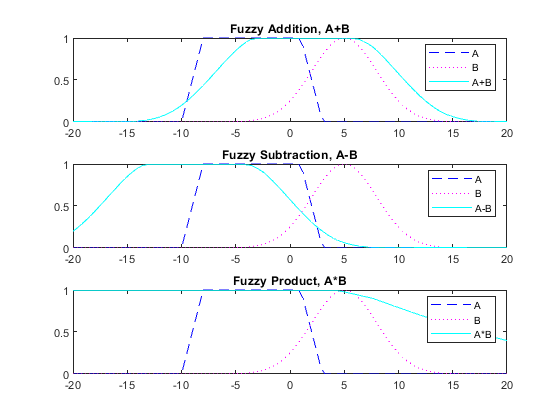

figure
subplot(3,1,1)
plot(x,A,'b--',x,B,'m:',x,Csum,'c')
title('Fuzzy Addition, A+B')
legend('A','B','A+B')
subplot(3,1,2)
plot(x,A,'b--',x,B,'m:',x,Csub,'c')
title('Fuzzy Subtraction, A-B')
legend('A','B','A-B')
subplot(3,1,3)
plot(x,A,'b--',x,B,'m:',x,Cprod,'c')
title('Fuzzy Product, A*B')
legend('A','B','A*B')